%冲激响应不变法
wp=0.2*pi;
ws=0.3*pi;
Rp=3;
Rs=30;

Fs=1e5;
OmegaP=wp*Fs;
OmegaS=ws*Fs;

[N,OmegaC]=buttord(OmegaP,OmegaS,Rp,Rs,'s');
[z0,p0,k0]=buttap(N);

p=p0*OmegaC; z=z0*OmegaC;
k=k0*OmegaC^N;

ba=k*real(poly(z));
aa=real(poly(p));

[bd,ad]=impinvar(ba,aa,Fs);

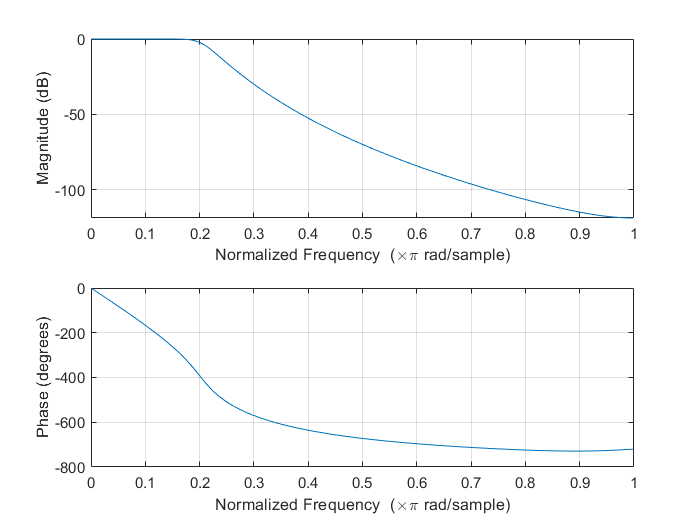

freqz(bd,ad);

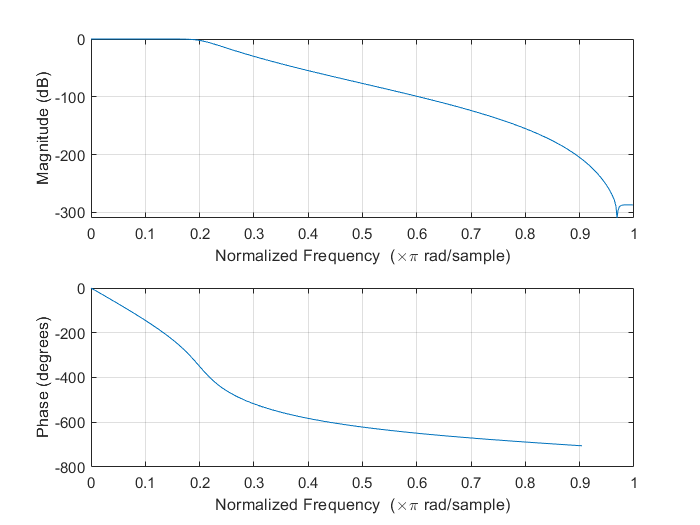

wp=0.2*pi;
ws=0.3*pi;
Rp=3;
Rs=30;

Fs=1e5;
OmegaP=2*Fs*tan(wp/2);    %频率预变换
OmegaS=2*Fs*tan(ws/2);

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k);       %由零点、极点、增益确定传输函数的分子与分母的系数 
[b,a]=lp2lp(Bp,Ap,Wn);      %模拟低通滤波器到模拟低通滤波器的转换 

[bz,az]=bilinear(b,a,Fs);   
figure(1); 
freqz(bz,az);

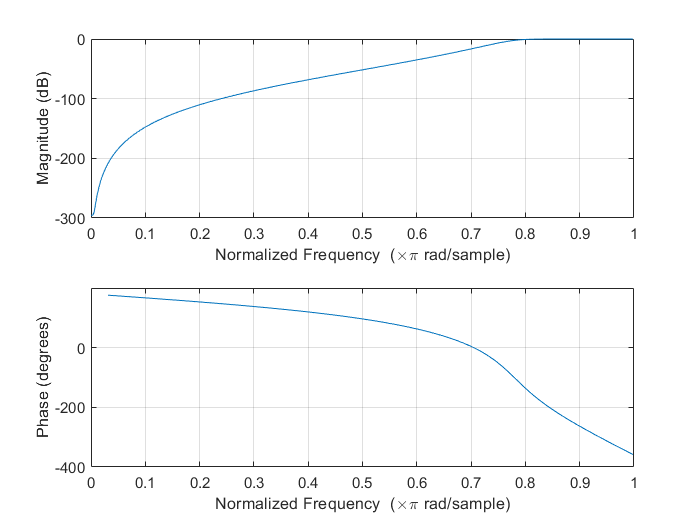

fp=400;
fs=300;
Fs=1000;
Rp=3;  Rs=35;

wp=2*pi*fp/Fs;
ws=2*pi*fs/Fs;

OmegaP=2*Fs*tan(wp/2);
OmegaS=2*Fs*tan(ws/2);

[N,Wn]=buttord(OmegaP,OmegaS,Rp,Rs,'s');  %选择模拟巴特沃斯低通滤波器的最小阶数 
[z,p,k]=buttap(N);          %创建巴特沃斯模拟低通滤波器 
[Bp,Ap]=zp2tf(z,p,k);       %由零点、极点、增益确定传输函数的分子与分母的系数 
[b,a]=lp2hp(Bp,Ap,Wn);      %模拟低通滤波器到模拟低通滤波器的转换 

[bz,az]=bilinear(b,a,Fs);   
figure(1); 
freqz(bz,az);

%6.3(2)
%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------

fp=[300 400];fs=[200 500];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=2000;
rp=3;rs=40;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap = 	1.0e+03 *

    2.0381    2.9062


was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0    0.1253


a =     1.0000    0.5816    1.1691    0.4048    0.1770


bw=wap(2)-wap(1)

bw = 868.0683

w0=sqrt(wap(1)*wap(2))

w0 = 2.4337e+03

[bt,at]=lp2bp(b,a,w0,bw)

bt = 	1.0e+10 *

    7.1147   -0.0000   -0.0000         0         0


at = 	1.0e+27 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0001    1.2308


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 = 	1.0e+-3 *

    0.0702   -0.0000   -0.2808   -0.0000    0.4212   -0.0000   -0.2808   -0.0000    0.0702


az1 =     1.0000   -3.5495    8.4668  -12.8267   14.9115  -12.2548    7.7286   -3.0945    0.8331


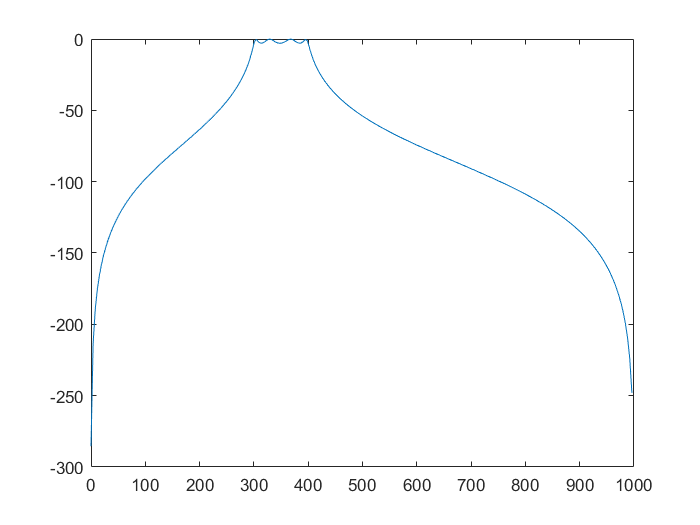

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))

%----------------------------------------------------------------------------
% exa060603.m, for example 6.6.3;
% To design IIR Butteworth bandstop DF by analog-lowpass,
% ---------------------------------------------------------------------------

fp=[44 56];fs=[47 53];
%wp=[.19*pi 0.21*pi];ws=[.198*pi 0.202*pi];
Fs=1000;
rp=3;rs=50;
wp=fp*2*pi/Fs;ws=fs*2*pi/Fs;
%
% Firstly to finish frequency prewarping;
wap=2*Fs*tan(wp./2)

wap =   278.2345  355.5340


was=2*Fs*tan(ws./2);
[n,wn]=cheb1ord(wap,was,rp,rs,'s');
% Note: 's'!
[z,p,k]=cheb1ap(n,rp);
[b,a]=zp2tf(z,p,k)

b =          0         0         0         0         0         0    0.0313


a =     1.0000    0.5707    1.6628    0.6906    0.6991    0.1634    0.0442


bw=wap(2)-wap(1)

bw = 77.2995

w0=sqrt(wap(1)*wap(2))

w0 = 314.5184

[bt,at]=lp2bs(b,a,w0,bw)

bt = 	1.0e+29 *

    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0000   -0.0000    0.0004   -0.0000    6.6337


at = 	1.0e+29 *

    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0000    0.0007    0.0270    9.3703


%
% Note: z=(2/ts)(z-1)/(z+1);
[bz1,az1]=bilinear(bt,at,Fs)

bz1 =     0.6089   -6.9539   36.7445 -118.7534  261.3934 -412.7774  479.4758 -412.7774  261.3934 -118.7534   36.7445   -6.9539    0.6089


az1 =     1.0000  -11.1145   57.1903 -180.1085  386.5896 -595.7513  675.8540 -568.7217  352.3334 -156.7382   47.5337   -8.8256    0.7589


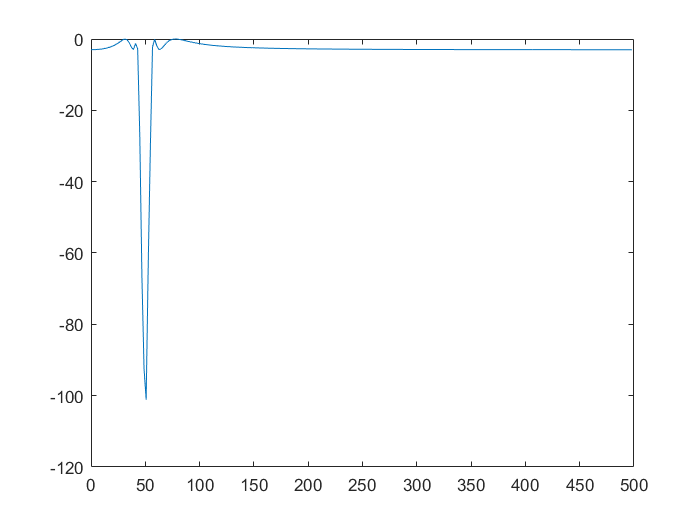

[h,w]=freqz(bz1,az1,256,Fs);
figure(1)
plot(w,20*log10(abs(h)))